% exp struct.
exp_date = '2017-10-03';
%
dirpath = pwd

dirpath = 'C:\Users\scanimage\Documents\MATLAB\DATA-juyoung\1011-GCamp6s_b5-mcherry_mouse'

h5_dir = dir([dirpath, '/*.h5']);
tif_dir = dir([dirpath, '/*.tif']);
%
 h5_filenames = {h5_dir.name};
tif_filenames = {tif_dir.name};
% count file numbers using h5 files
n_file = length(h5_filenames);
%
fprintf("%s\n", h5_dir.name)
%fprintf("%s\n", tif_dir.name)

%% (h5) Loading files
% List all the files loaded and see # of sweeps
idx_files = 1:n_file; % can be just one id.
%idx_files = [5, 6];
%
data_h5  = cell(1, length(idx_files));
data_tif = cell(1, length(idx_files));
%
for i = idx_files
    data_h5{i} = ws.loadDataFile(h5_filenames{i});
    % I modified the function 'loadDataFile.m': NAIChannels to NAITerminals 2017 0921 Juyoung
    fprintf("%d: %s\n",i, h5_filenames{i});
    fprintf("           header.SweepDuration: %.2f (s)\n", data_h5{i}.header.SweepDuration);
    fprintf("    header.Acquisition.Duration: %.2f (s)\n", data_h5{i}.header.Acquisition.Duration);
    
    % filename of h5
    filename_split = strsplit(h5_filenames{i}, '.h5');
    filename = filename_split{1};
    % file id for sync tif files as logical arrays
    sync_tif_ids = contains(tif_filenames, filename);
    sync_tif_files = tif_filenames(sync_tif_ids);
    n_sync_files = numel(sync_tif_files);
    % load sync tif files
    data_tif{i} = cell(1, n_sync_files);
    for j =1:n_sync_files
        Aout = ScanImageTiffReader(filename);
        data_tif{i}{j}.header = Aout.metadata;
        data_tif{i}{j}.stack  = Aout.data;
    end
    fprintf("    ScanImage files: %d were loaded.", n_sync_files);
end

1: rgc_001_0001.h5


           header.SweepDuration: 500.00 (s)


    header.Acquisition.Duration: 500.00 (s)


    ScanImage files: 0 were loaded.

**data{i} - hedaer + sweep X n times**

1-th file: rgc_001_0001.h5


n_sampling = 2720369

n_ch = 2

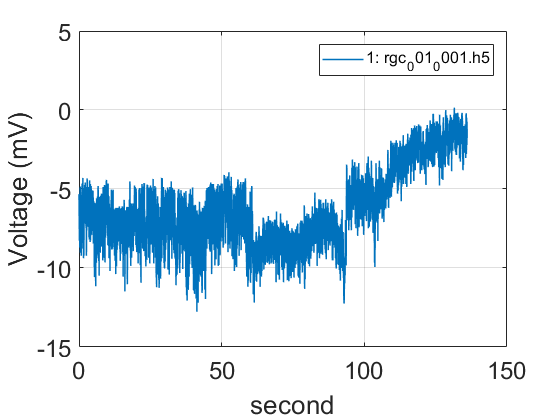

% cell (or recording) # -> cell array
% sweeps -> array
% Initialize data matrix with zeros instead of empty matrix in case sampling varied over multiple sweeps
for i = idx_files
    fprintf("%d-th file: %s\n", i, h5_filenames{i});
    sweep_names = fieldnames(data_h5{i});
    % exclude 'header' field
    sweep_names = sweep_names(2:end);
    %
    n_sweeps = length(sweep_names);
    % Initialize data matrix with zeros instead of empty matrix in case sampling varied over multiple sweeps
    [n_sampling, n_ch] = size(getfield(data_h5{i}, sweep_names{1}, 'analogScans')) % guess by first sweep data
    vol_sweeps = zeros(n_sampling,n_sweeps);
    cur_sweeps = zeros(n_sampling,n_sweeps);
    %
    sampling_rate = data_h5{i}.header.Acquisition.SampleRate;
    data_h5{i}.times = (1:n_sampling)*(1/sampling_rate); 
    figure;
    %
    for j = 1:n_sweeps
        sweep = getfield(data_h5{i}, sweep_names{j});
        
        vol_temp = sweep.analogScans(:,1); % voltage channel
        cur_temp = sweep.analogScans(:,2); % current channel
        
        n_sampling = length(sweep.analogScans);
        % Assume 20K sampling !!!
        times_temp = (1:n_sampling)*0.00005; 
        % simple plot
        plot(times_temp, vol_temp, 'LineWidth', 1.1); grid on; hold on;
        xlabel('second'); ylabel('Voltage (mV)');
        ax = gca; Fontsize = 18;
        ax.XAxis.FontSize = Fontsize;
        ax.YAxis.FontSize = Fontsize;
        %
        vol_sweeps(1:n_sampling, j) = vol_temp;
        cur_sweeps(1:n_sampling, j) = cur_temp;
    end
    data_h5{i}.voltage = vol_sweeps;
    data_h5{i}.current = cur_sweeps;
    hold off;
    ax = legend([num2str(i),': ',h5_filenames{i}]);
    ax.FontSize=12;
end

## imaging

% Inspection of one file (i=50th file?)
i=2; 
filename = [dirpath,'/',tif_filenames{i}];
%
img = ScanImageTiffReader(filename);
header = img.metadata;
vol = img.data;

h = interpret_SI_header_from_TiffReader(header)

    '1'    '3'    '4'



h = struct with fields:
    FramesPerFile: 3600
      channelSave: {'1'  '3'  '4'}


[row  col  d3  d4] = [256  256  6037  1]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]


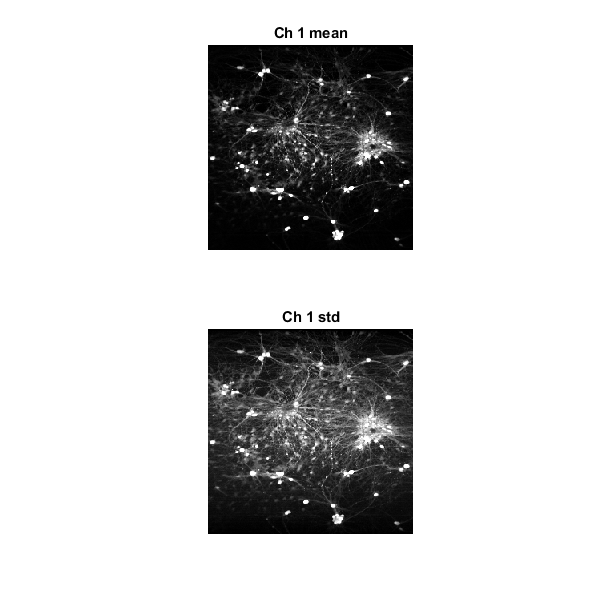

% dim for frame?
% e.g. SI.hScan2D.logFramesPerFile = 30;
[row, col, n_frames] = size(vol);
f_dim = 3;

% Assume Ch #
% e.g. SI.hChannels.channelSave = [3;4]
N_ch = 2;
n_frames_ch = n_frames/N_ch;

% de-interleave into channels
id_ch = mod((1:n_frames)-1, N_ch)+1;
ch_1_AI = vol(:,:,id_ch==1); % Analog input
ch_2_AI = vol(:,:,id_ch==2);

% for all channels
AI_ch = cell(N_ch, 1);
for i=1:N_ch
    AI_ch{i} = vol(:,:,id_ch==i); % Analog input
end

% check the image (any channels?)
figure; [mean_vol_ch1, std_vol_ch1] = myimgstat(ch_1_AI);

[row  col  d3  d4] = [256  256  6037  1]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]


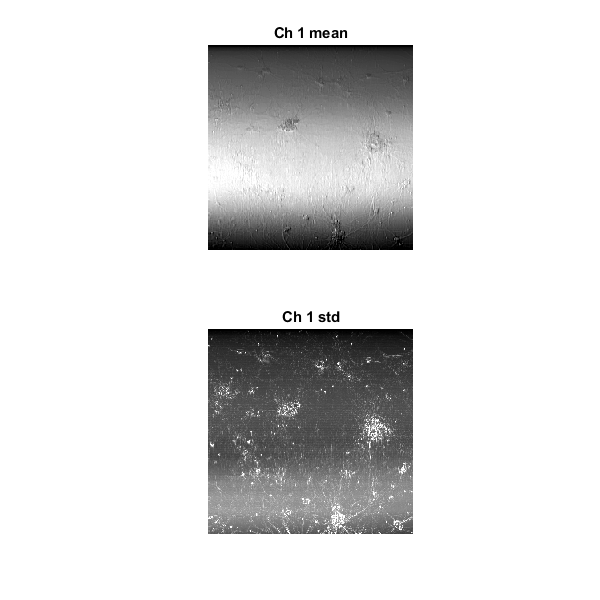

figure; [mean_vol_ch2, std_vol_ch2] = myimgstat(ch_2_AI);

% empty Vol
%img = zeros(d(1),d(2),d(3)*N);
%N_tot_frame = N*d(3);

% if frames are distributed over multiple files, merge into one matrix
ch1 = []; ch2 = []; ch3 = [];
for i=1:n_files
    filename = [dirpath,'/',file_list{i}];
    vol = ScanImageTiffReader(filename).data();
    ch1_vol = vol(:,:,id_ch==1); % Analog input
    ch2_vol = vol(:,:,id_ch==2);
    %
    ch1 = cat(3, ch1, ch1_vol);
    ch2 = cat(3, ch2, ch2_vol);
    %i_frame = (i-1)*d(3)+1; 
    %img(:,:,i_frame:(i_frame+d(3)-1)) = ScanImageTiffReader(filename).data();
end

[row  col  d3  d4] = [256  256  9000  1]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]


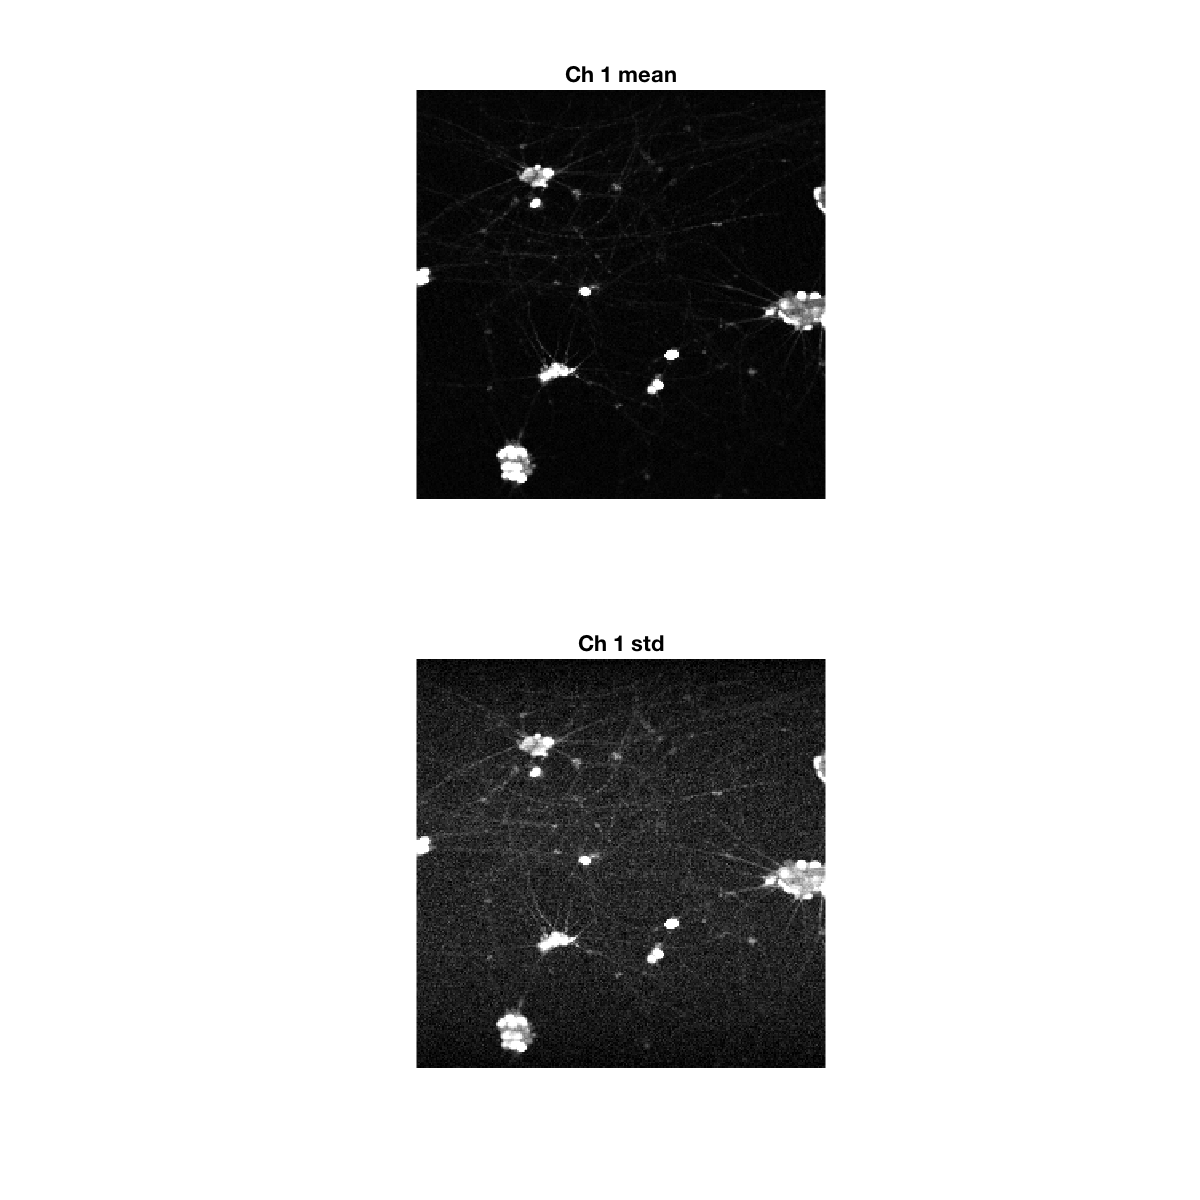

figure; [mean_ch1, std_ch1] = myimgstat(ch1);

[row  col  d3  d4] = [256  256  9000  1]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]
[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.010  0.990]


[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.020  0.980]


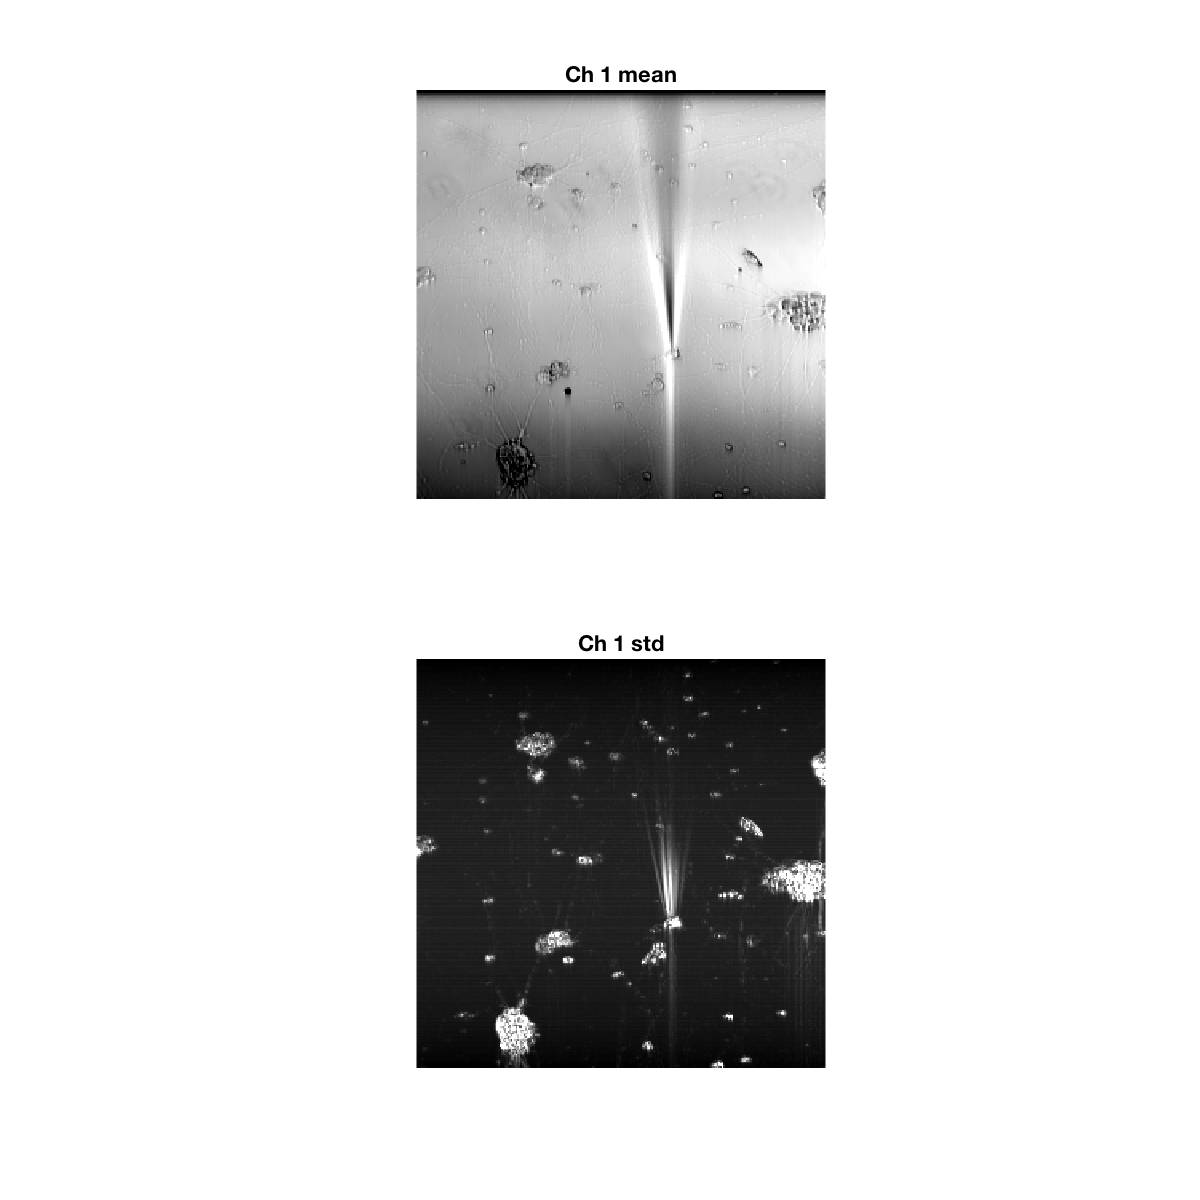

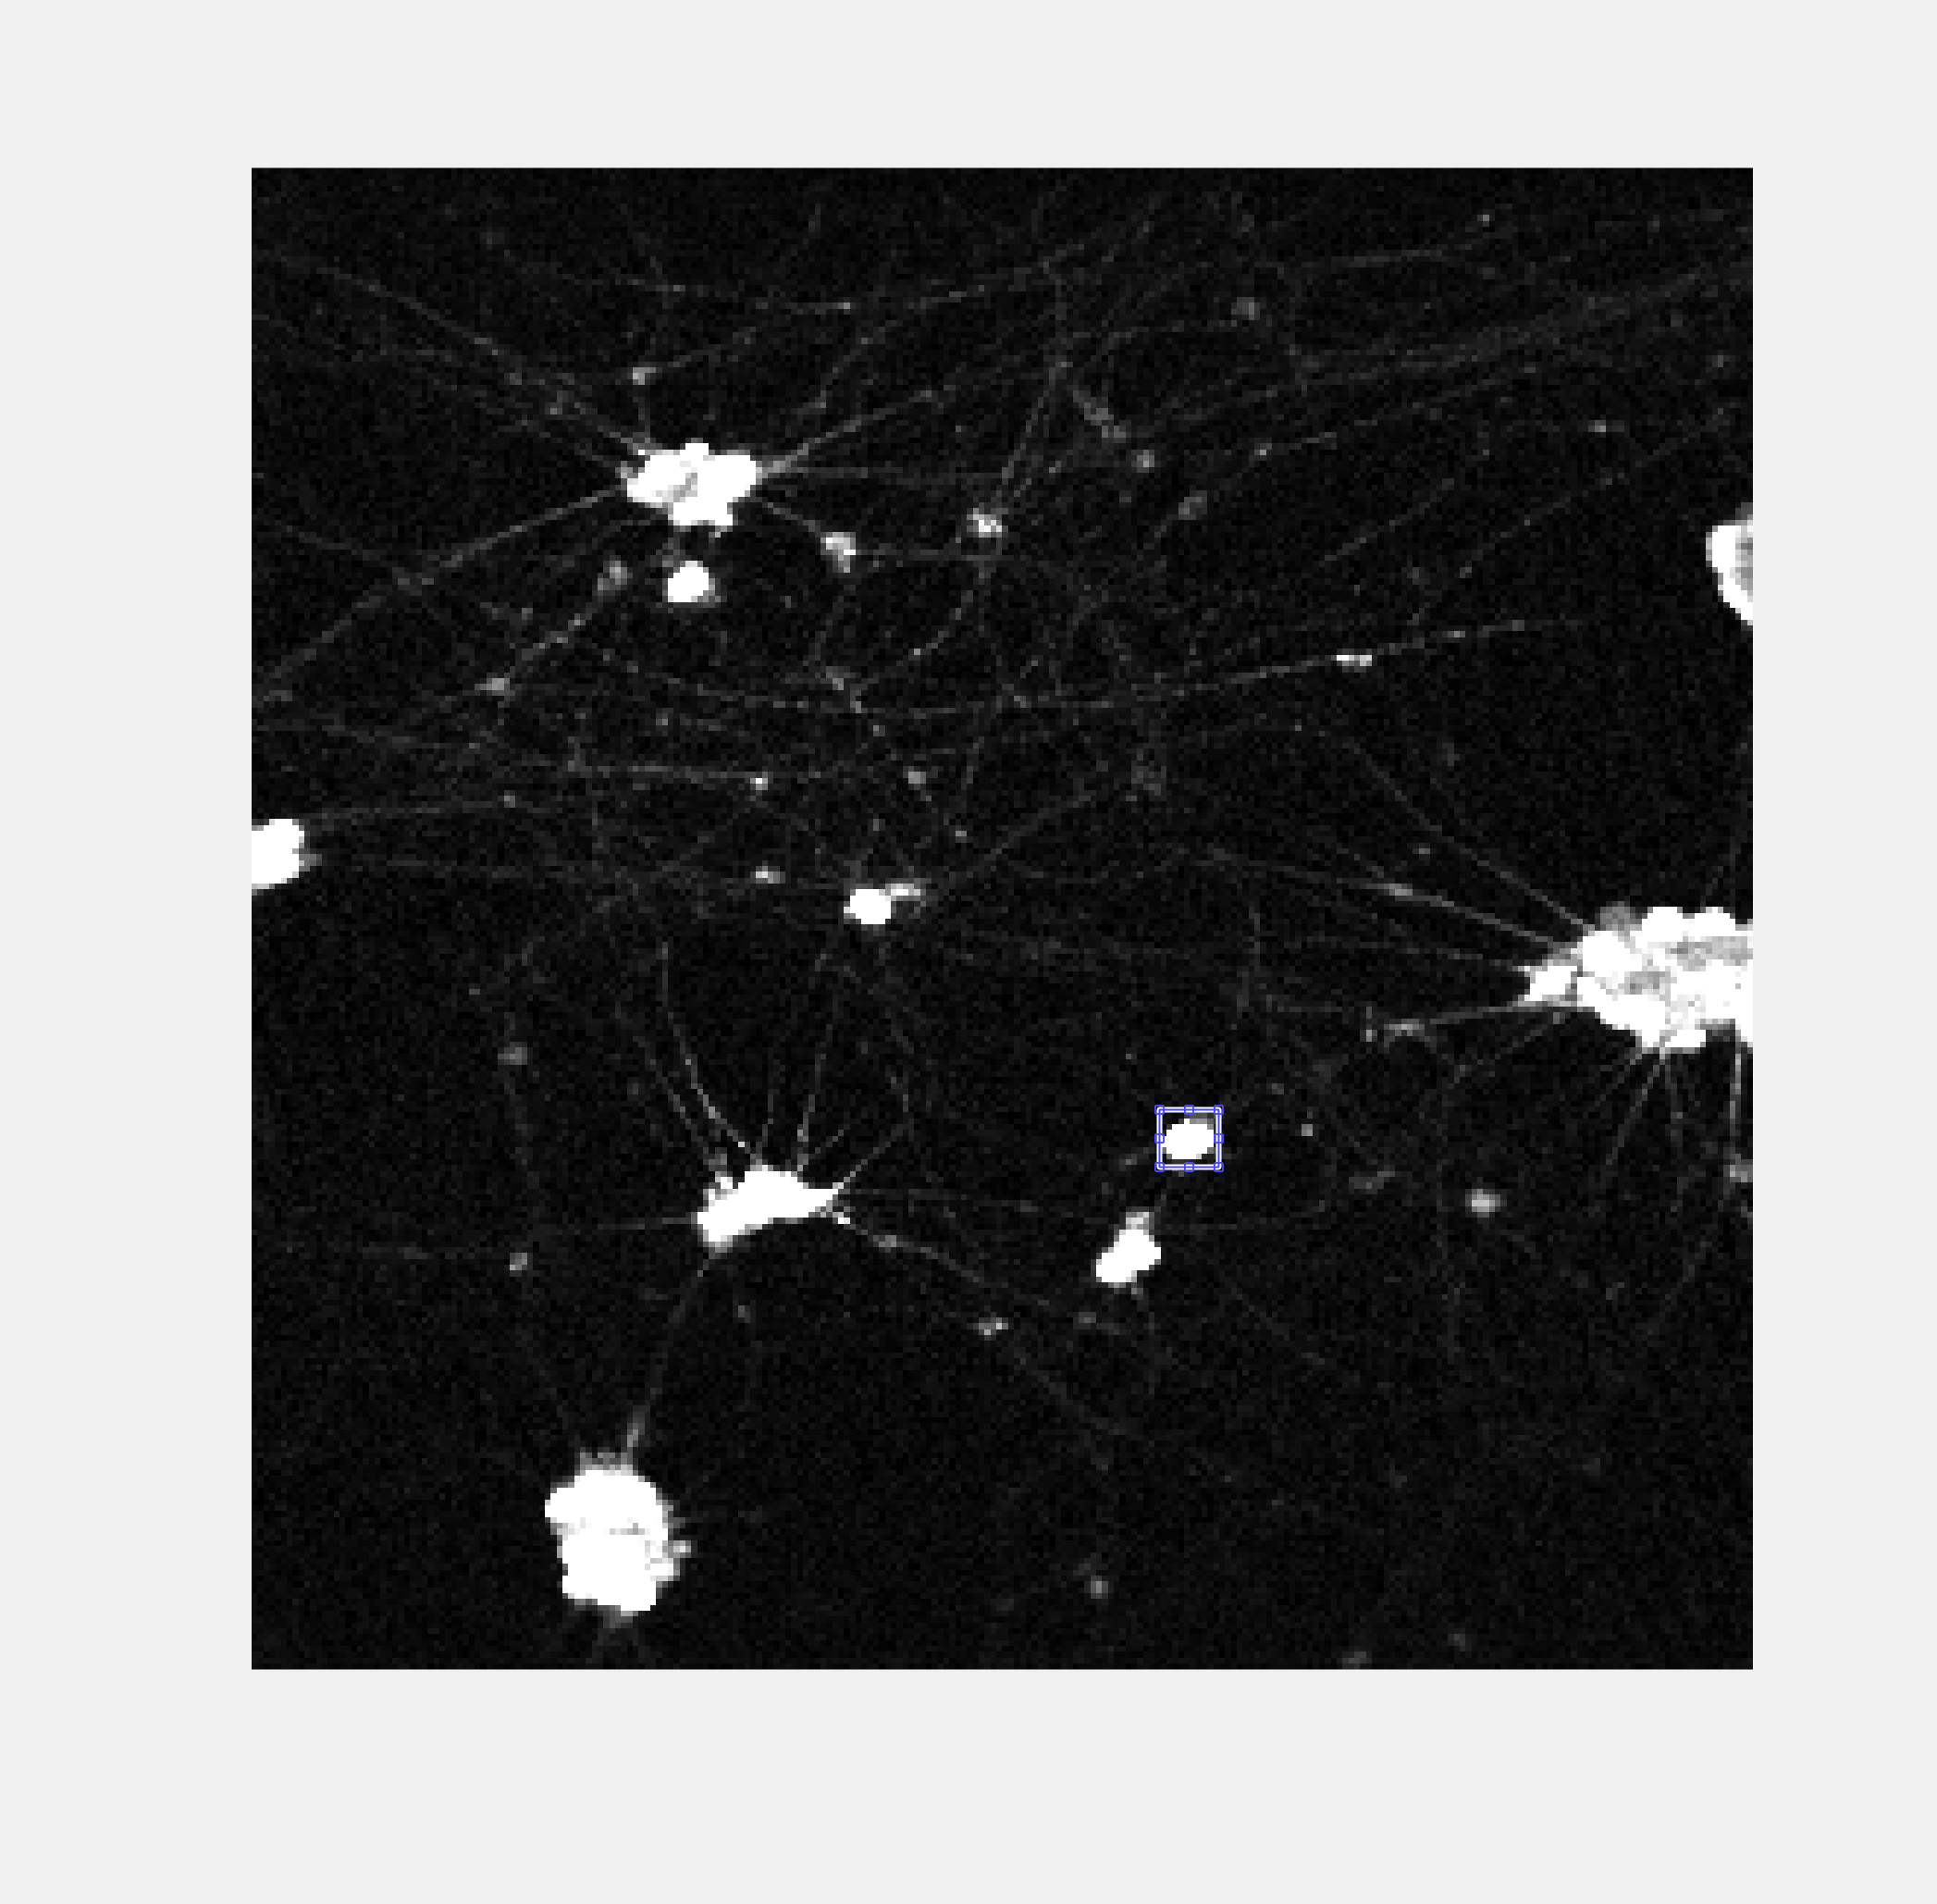

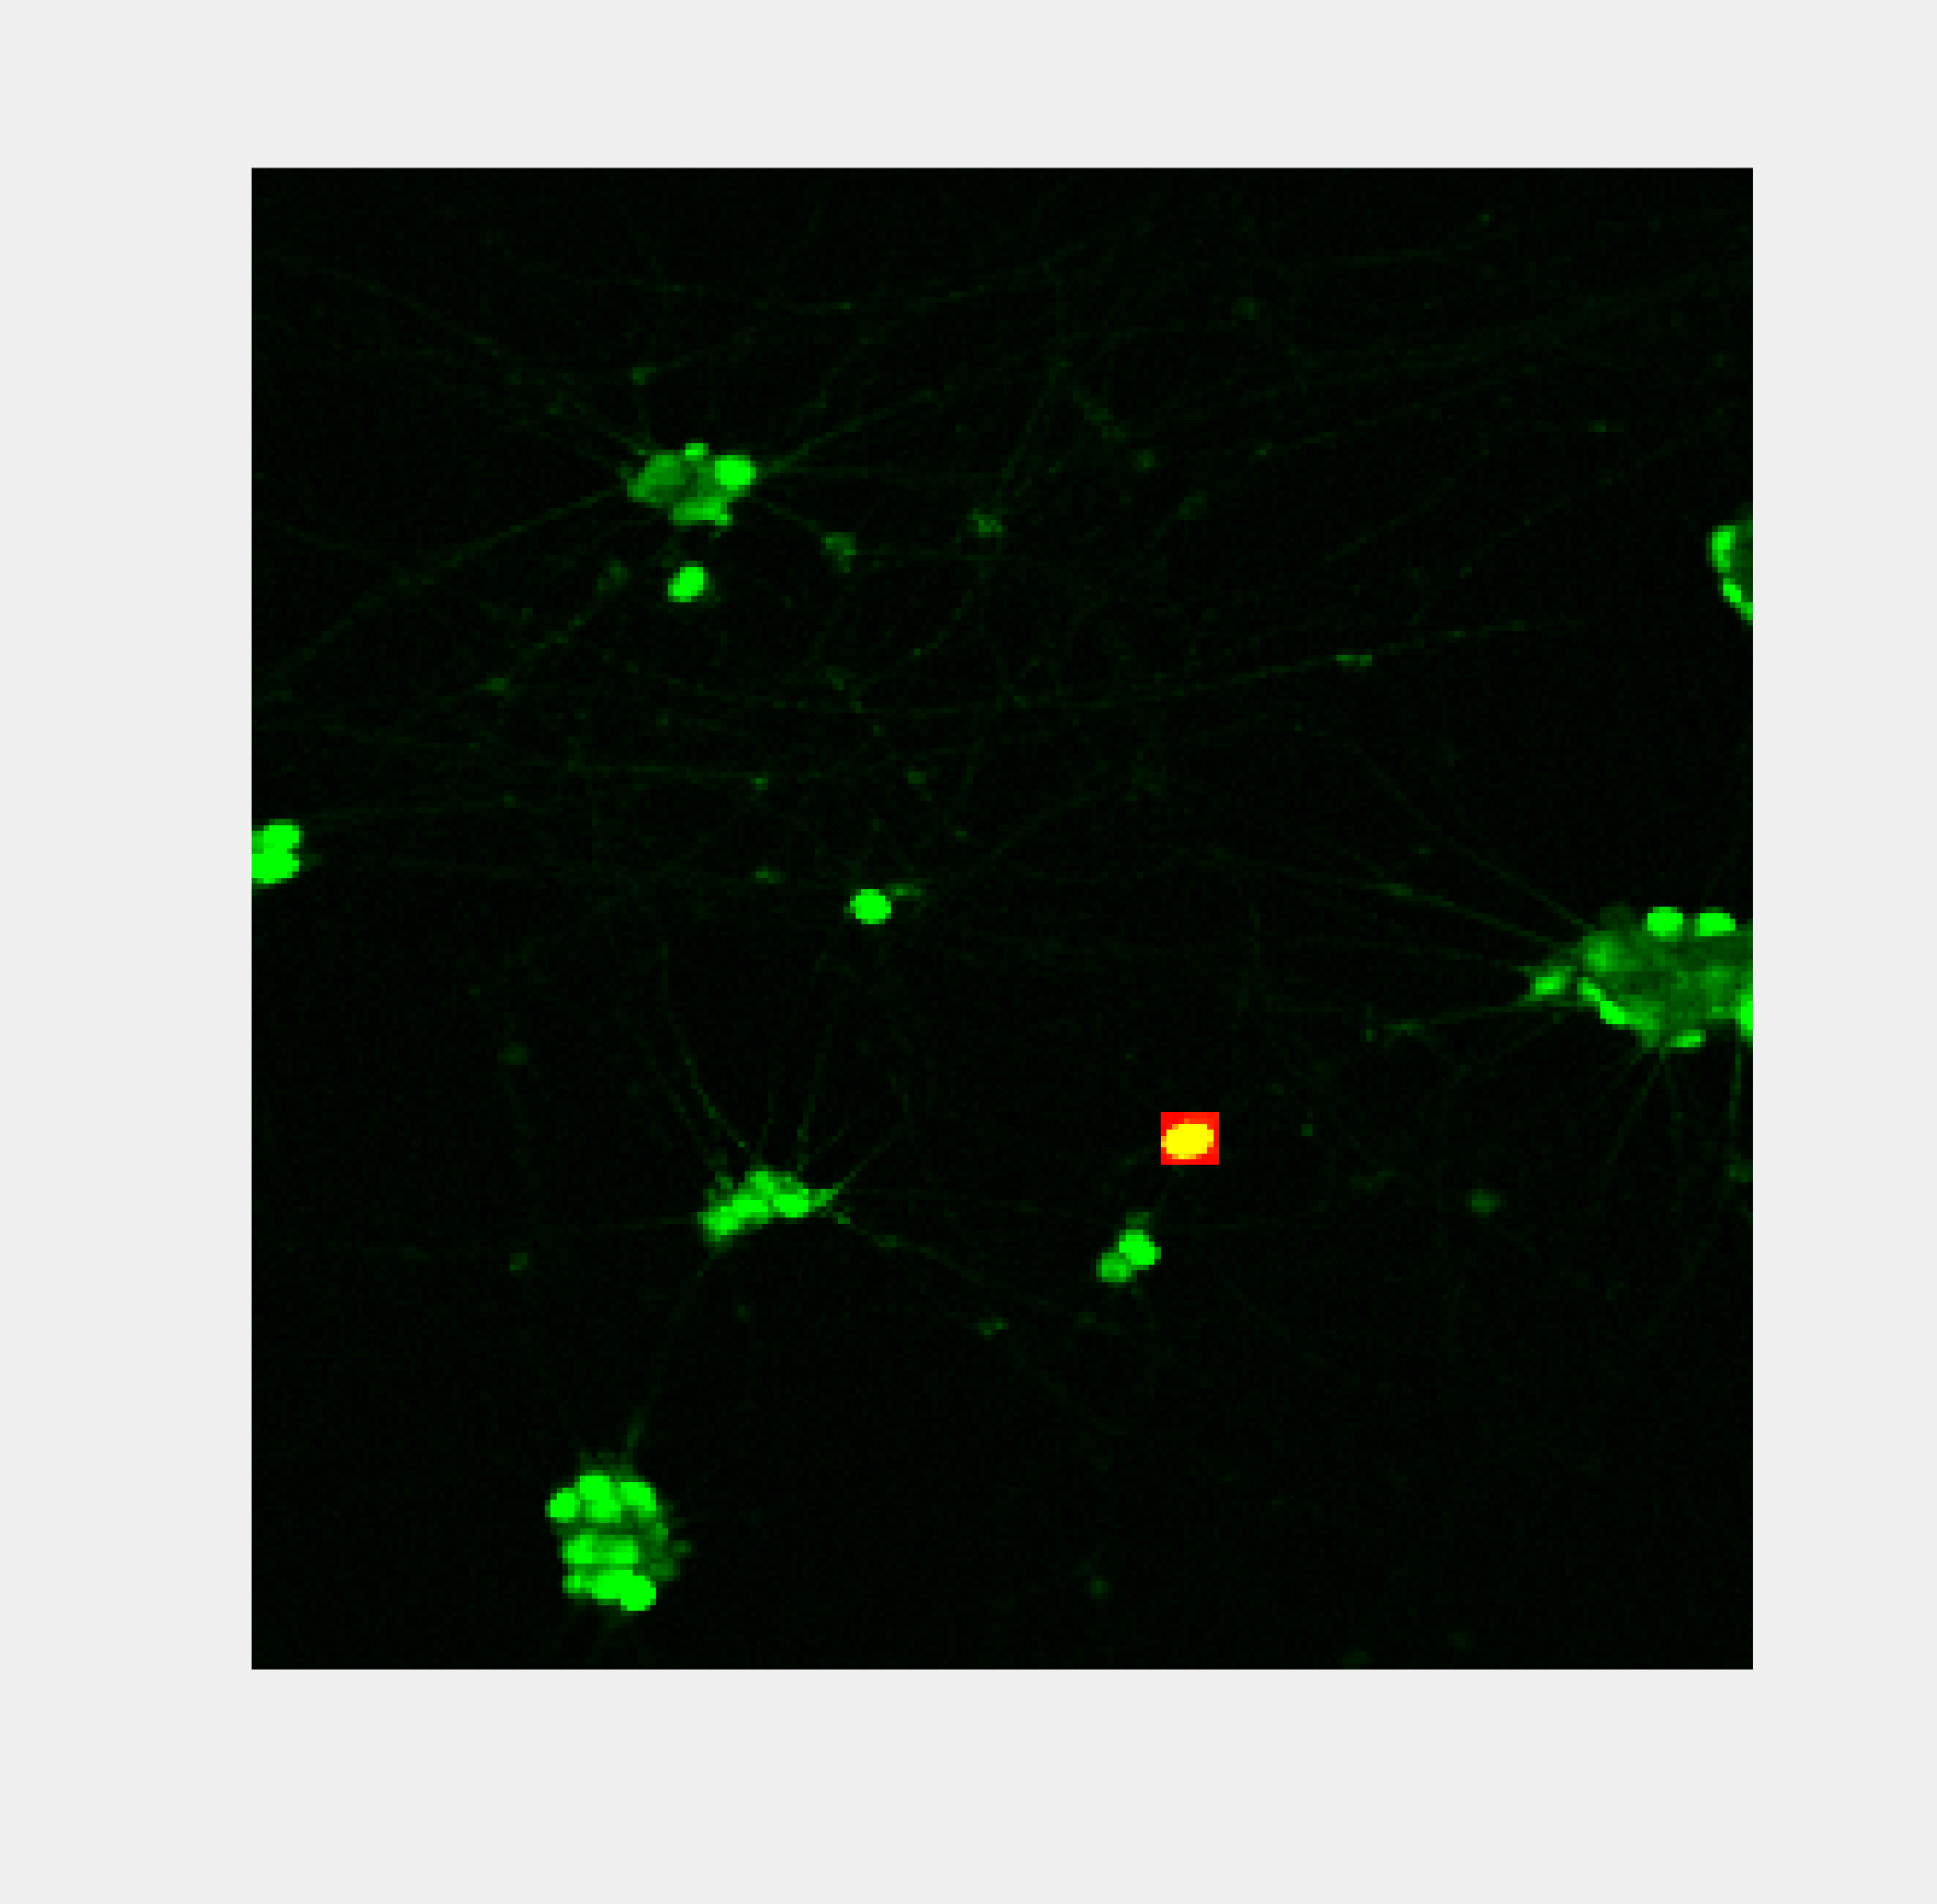

figure; [mean_ch2, std_ch2] = myimgstat(ch2);

## ROI intensity over time

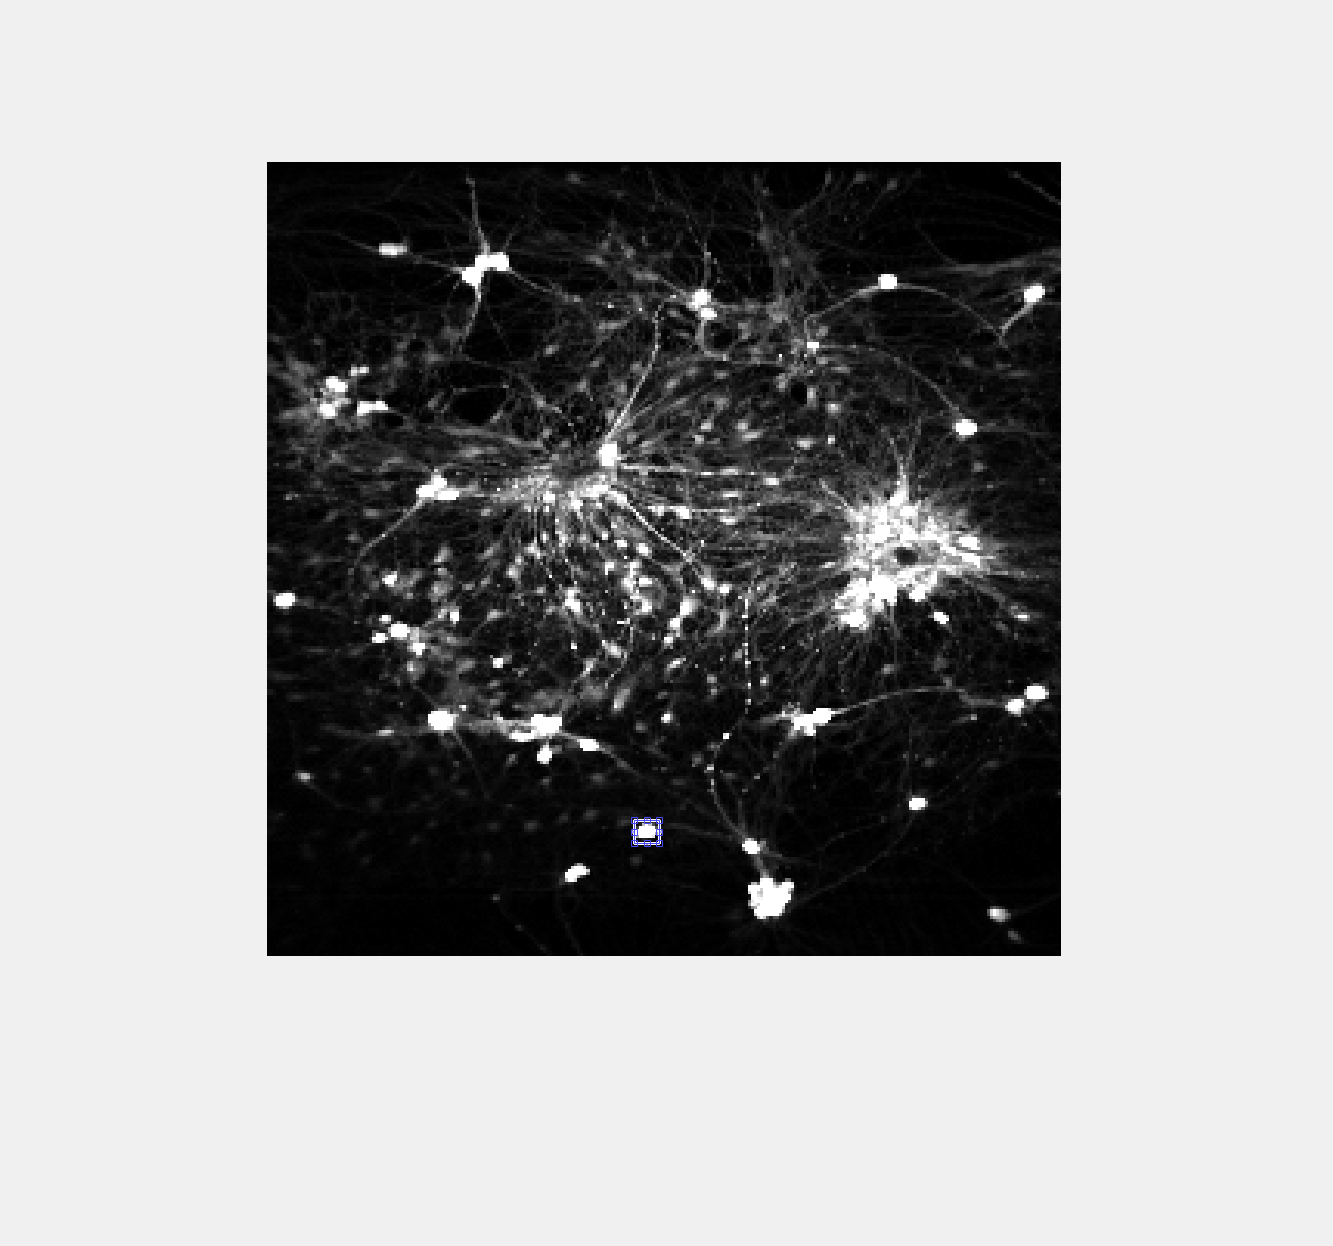

%
figure;

[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.020  0.980]
7 ROI was selected.


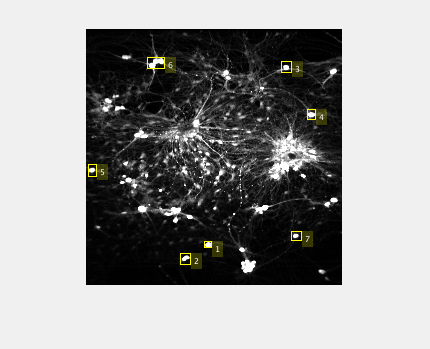

%in = squareRoi(mean_ch1);
roi_array = multiRoi(mean_vol_ch1);

[row, col, n_roi] = size(roi_array);

% roi -> cell array
roi_img = cell(n_roi, N_ch);
roi_avg = cell(n_roi, N_ch);
AI_ch_reshaped = cell(N_ch, 1);
%
roi_reshaped = reshape(roi_array, [], n_roi);
roi_reshaped = logical(roi_reshaped);

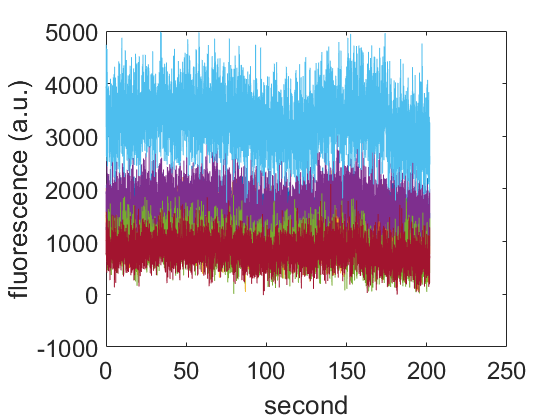

% Average over individual ROI

for j=1:N_ch
    
    AI_ch_reshaped{j} = reshape(AI_ch{j}, [], n_frames_ch);
    
    for i=1:n_roi
        roi_img{i,j} = AI_ch_reshaped{j}(roi_reshaped(:,i), :); 
        roi_avg{i,j} = sum(roi_img{i, j}, 1);
    end
    
end    

%
ifi = 1/29.9;
f_times = (1:n_frames_ch)*ifi;
%
figure; 
for i = 1:n_roi
plot(f_times, roi_avg{i,1}); hold on
xlabel('second'); ylabel('fluorescence (a.u.)');
        ax = gca; Fontsize = 18;
        ax.XAxis.FontSize = Fontsize;
        ax.YAxis.FontSize = Fontsize;
end
hold off

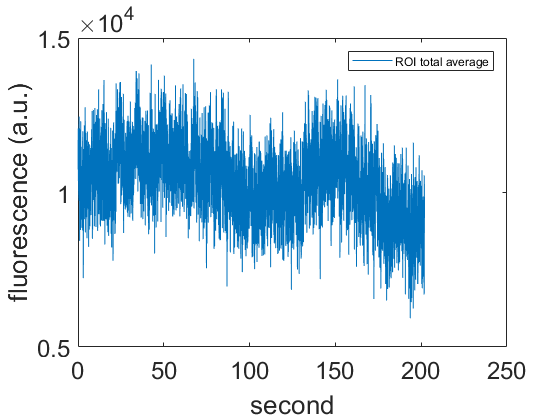

roi_avg_ch1 = cell2mat(roi_avg(:,1));
roi_tot_ch1 = sum(roi_avg_ch1, 1);
figure;
plot(f_times, roi_tot_ch1);
xlabel('second'); ylabel('fluorescence (a.u.)');
        ax = gca; Fontsize = 18;
        ax.XAxis.FontSize = Fontsize;
        ax.YAxis.FontSize = Fontsize;
        legend('ROI total average');

%

## Did Ca image align with KCl response?

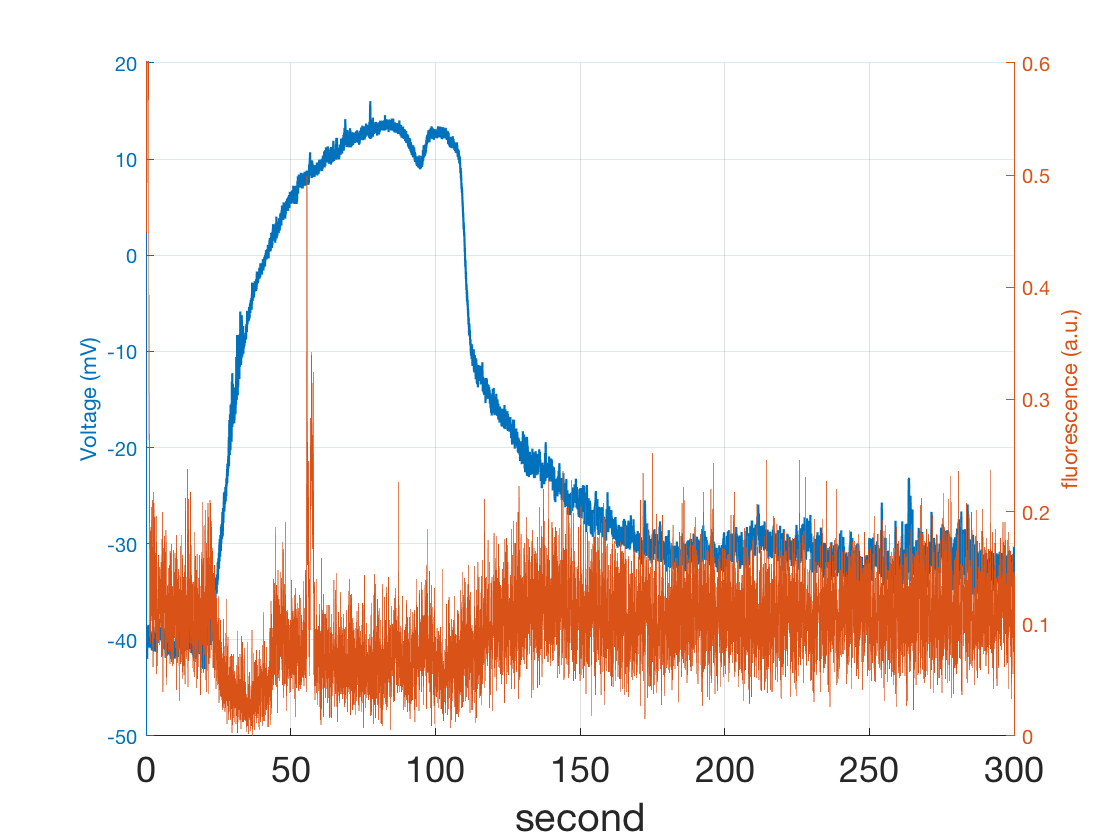

figure; hold on;
yyaxis left
plot(data_h5.times{7},data_h5.voltage{7},'LineWidth', 1.1); grid on;
    xlabel('second'); ylabel('Voltage (mV)');
    ax = gca; Fontsize = 18;

yyaxis right
plot(f_times, scaled(roi_trace));
    ylim([0, 0.6])
    xlim([0, 300])
    ylabel('fluorescence (a.u.)');
    ax = gca; Fontsize = 18;
    ax.XAxis.FontSize = Fontsize;

    ax.YAxis.FontSize = Fontsize;

Expected one output from a curly brace or dot indexing expression, but there were 2 results.

hold off;

cla

## ROI2

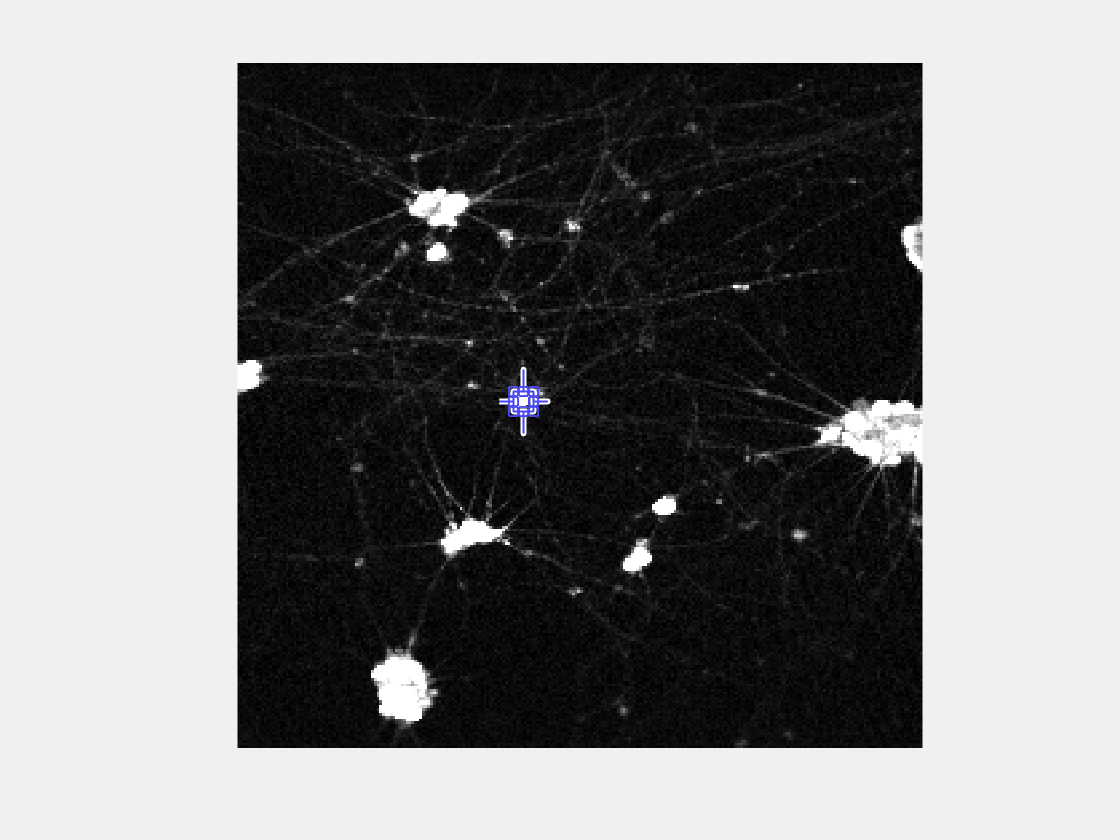

% id for intracellular recording? 
id_recording = 7;

%
figure;

[row  col  d3  d4*d5*..] = [256  256  1  1]   Tol = [0.020  0.980]


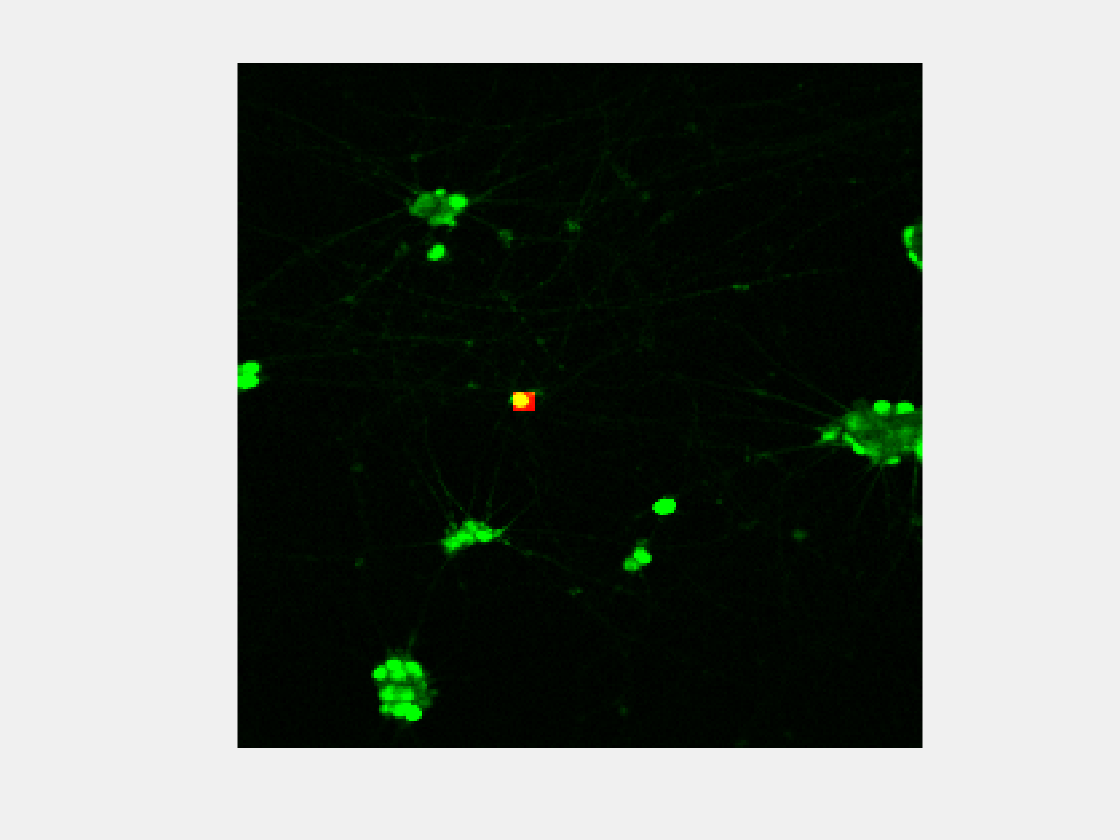

in = squareRoi(mean_ch1);

%
n_frames_ch = dim_ch1(f_dim);

Undefined function or variable 'f_dim'.

%
in_1D = reshape(in, [], 1);
ch1_reshaped = reshape(ch1, [], n_frames_ch);
roi_img = ch1_reshaped(in_1D, :);
roi_trace = sum(roi_img,1);
%
ifi = 1/29.9;
f_times = (1:n_frames_ch)*ifi;
%
figure; 
plot(f_times,roi_trace);
xlabel('second'); ylabel('fluorescence (a.u.)');
        ax = gca; Fontsize = 18;
        ax.XAxis.FontSize = Fontsize;
        ax.YAxis.FontSize = Fontsize;        legend(file_list{1});
%
figure; hold on;
yyaxis left
plot(data_h5.times{7},data_h5.voltage{7},'LineWidth', 1.1); grid on;
    xlabel('second'); ylabel('Voltage (mV)');
    ax = gca; Fontsize = 18;

yyaxis right
plot(f_times, scaled(roi_trace));
    ylim([0, 0.6])
    xlim([0, 300])
    ylabel('fluorescence (a.u.)');
    ax = gca; Fontsize = 18;
    ax.XAxis.FontSize = Fontsize;
    ax.YAxis.FontSize = Fontsize;
hold off;

cla